# EMG Data Processor - Smoothing and Visualizing Tool

This gives a good visual of the differences between tests, but RMS is the more standard way to present collected data

This code also has a few checks for repeated times, anything out of order, or outliers that don't make sense which is good to use as you're figuring out Consensys

clear; clc; close all;

INPUT_PATH  = "EMG_15lb.xlsx";     % input file
OUTPUT_PATH = "w15lb_data.csv";    % output CSV - can use this in RMS if you comment out filter (butter)

FILTER_TYPE = "lowpass";              % "lowpass" or "bandpass"

LOWPASS_CUTOFF_HZ = 10.0;             % for lowpass smoothing
BANDPASS_LOW_HZ   = 20;              % for bandpass
BANDPASS_HIGH_HZ  = 450;

FILTER_ORDER = 4;                     % 2–4 is a good default (filtfilt makes it effectively sharper)

TIMESTAMP_IS_MS = true;               % true if timestamps are milliseconds


% Baseline correction settings (align start means)
BASELINE_SECONDS = 0.5;               % use first 0.5s to compute baseline mean

% Load data
data = readmatrix(INPUT_PATH);

%Check data was imported from Consensys without gaps
disp("Any NaN in timestamps?");

Any NaN in timestamps?


disp(any(isnan(data(:,1))))

   0




disp("Any NaN in signals?");

Any NaN in signals?


disp(any(isnan(data(:,2:end)), "all"))

   0



%END CHECK

t_raw = data(:,1); % First channel that records time
X_raw = data(:,2:end); % EMG Channels

% Convert timestamps to seconds
if TIMESTAMP_IS_MS
    t_sec = t_raw / 1000.0;
else
    t_sec = t_raw;
end

% Sort by time (just in case)
[t_sec, idx] = sort(t_sec);
X_raw = X_raw(idx,:);

% Remove duplicate timestamps (keep first occurrence)
[~, uniqueIdx] = unique(t_sec, 'stable');
t_sec = t_sec(uniqueIdx);
X_raw = X_raw(uniqueIdx,:);

% Shift time to start at 0 for numerical stability
t_sec = t_sec - t_sec(1);

% Estimate sampling rate & create uniform grid
dt = diff(t_sec);
dt = dt(isfinite(dt) & dt > 0);

if numel(dt) < 10
    error("Not enough valid timestamps to estimate sampling rate.");
end

dt_med = median(dt);
fs_est = 1 / dt_med;

fprintf("Estimated Fs: %.3f Hz (dt ~ %.3f ms)\n", fs_est, 1000/fs_est);

Estimated Fs: 201.204 Hz (dt ~ 4.970 ms)



% Uniform time grid
t0 = t_sec(1);
t1 = t_sec(end);
t_grid = (t0 : 1/fs_est : t1).';   % column vector

% Interpolate to uniform grid
X_grid = interp1(t_sec, X_raw, t_grid, 'linear');

% Design filter
nyq = 0.5 * fs_est;

switch lower(FILTER_TYPE)
    case "lowpass"
        Wn = LOWPASS_CUTOFF_HZ / nyq;
        if ~(Wn > 0 && Wn < 1)
            error("Lowpass cutoff must be between 0 and Nyquist (%.3f Hz).", nyq);
        end
        [b,a] = butter(FILTER_ORDER, Wn, 'low');
        fprintf("Using %dth-order LOWPASS @ %.3f Hz\n", FILTER_ORDER, LOWPASS_CUTOFF_HZ);

    case "bandpass"
        Wn = [BANDPASS_LOW_HZ, BANDPASS_HIGH_HZ] / nyq;
        if ~(Wn(1) > 0 && Wn(2) < 1 && Wn(1) < Wn(2))
            error("Bandpass must satisfy 0 < low < high < Nyquist (%.3f Hz).", nyq);
        end
        [b,a] = butter(FILTER_ORDER, Wn, 'bandpass');
        fprintf("Using %dth-order BANDPASS %.3f–%.3f Hz\n", FILTER_ORDER, BANDPASS_LOW_HZ, BANDPASS_HIGH_HZ);

    otherwise
        error("FILTER_TYPE must be 'lowpass' or 'bandpass'.");
end

Using 4th-order LOWPASS @ 10.000 Hz


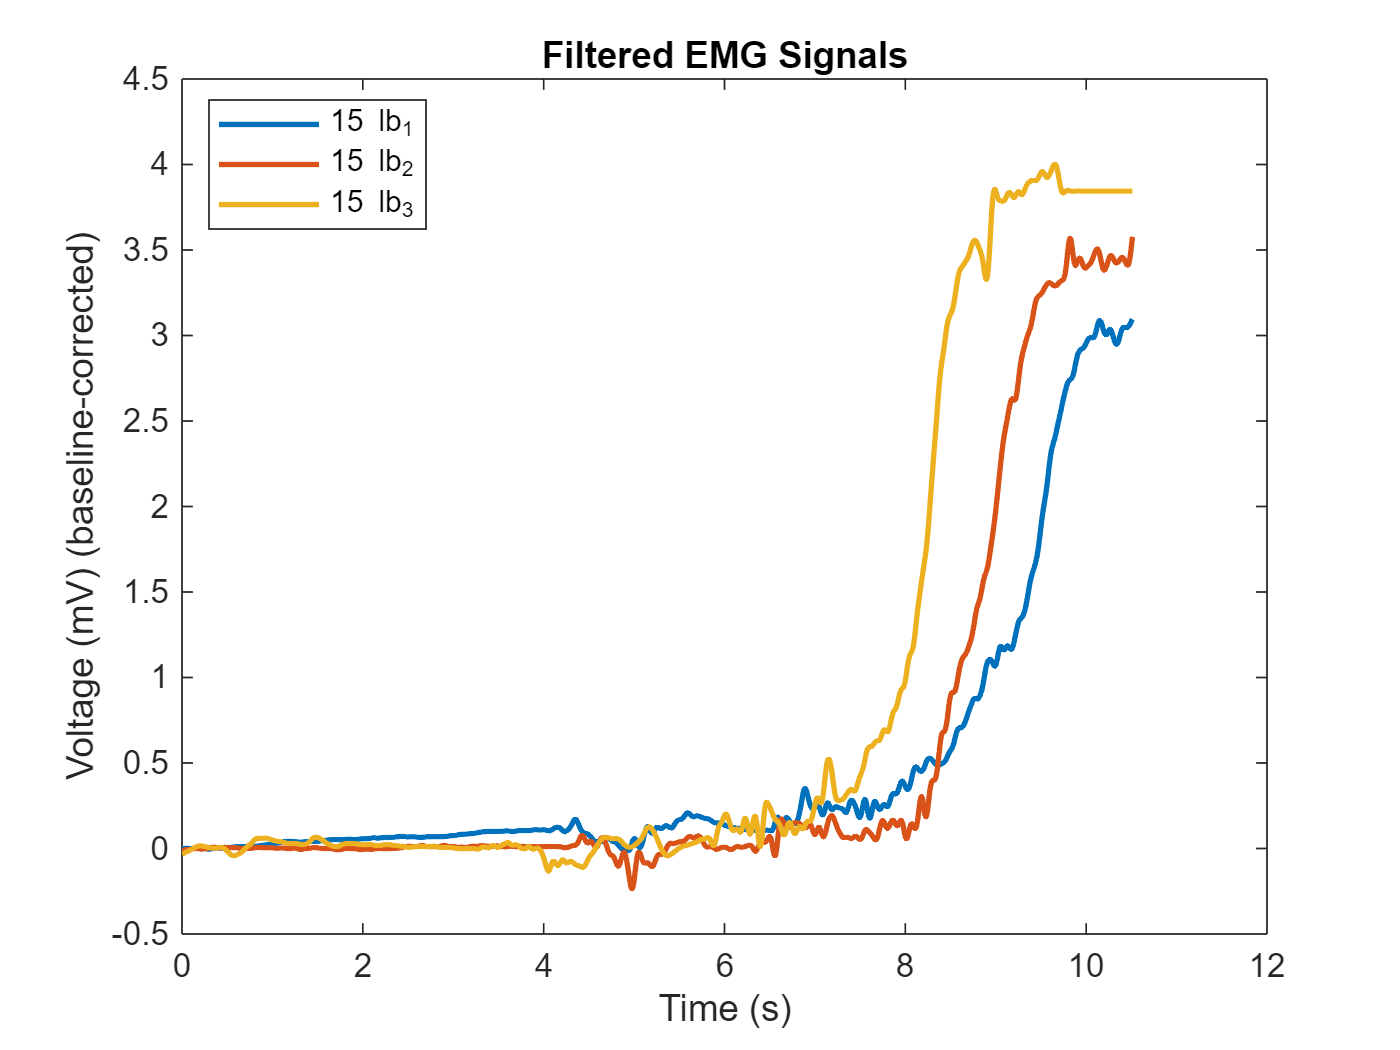


% Apply zero-phase filtering
% IMPORTANT: this line must exist BEFORE anything uses X_filt
X_filt = filtfilt(b, a, X_grid);     % filters each column independently

% Baseline-reset + labeled plot (FILTERED ONLY)
% Baseline correction (make all channels start at same mean)
idx0 = t_grid <= (t_grid(1) + BASELINE_SECONDS);
baseline = mean(X_filt(idx0,:), 1, "omitnan");
X_plot = X_filt - baseline;    % subtract baseline from each channel, center data around 0



% Labels: Channel 1..5 are weights; any extra columns get "Channel N"
labels = ["15 lb_1","15 lb_2","15 lb_3"];

nCh = size(X_plot,2);
if numel(labels) < nCh
    extra = "Channel " + (numel(labels)+1:nCh);
    labels = [labels, extra];
elseif numel(labels) > nCh
    labels = labels(1:nCh);
end

% Plot filtered signals
figure;
plot(t_grid, X_plot, "LineWidth", 1.6);

xlabel("Time (s)");
ylabel("Voltage (mV) (baseline-corrected)");
title("Filtered EMG Signals");
%legend(labels, "Location", "best");

% Save output (time + filtered channels, can be used in additional processing, i.e. RMS)
out = [t_grid, X_filt];
writematrix(out, OUTPUT_PATH);

fprintf("Saved filtered data to: %s\n", OUTPUT_PATH);

Saved filtered data to: w15lb_data.csv
